# **Tutorial IV: Sequence-to-Sequence Regression**

### Acknowledgment

- This tutorial was prepared by Najee Stubbs at the University of Arkansas (nistubbs@uark.edu). 

- The development of this tutorial was supported by a gift from MathWorks through the MathWorks Curriculum Development Support program. 

- The dataset and algorithms used in this tutorial are from *C. Dunlap, H. Pandey, E. Weems, and H. Hu, “Nonintrusive Heat Flux Quantification Using Acoustic Emissions During Pool Boiling,” Appl. Therm. Eng., 228, (2023) 120558. [*[*link*](http://%284%29c.%20dunlap%2C%20h.%20pandey%2C%20e.%20weems%2C%20and%20h.xn--%20hu%2C%20nonintrusive%20heat%20flux%20quantification%20using%20acoustic%20emissions%20during%20pool%20boiling%2C%20appl-z591fqg.%20therm.%20eng.%2C%20228%2C%20%282023%29%20120558.)*] and H. Hu and C. Heo, “Integration of Data Science into Thermal-Fluids Engineering Education”, in Proceedings of the ASME 2022 International Mechanical Engineering Congress and Exposition, Oct – Nov 2022, Columbus, OH, IMECE2022-88193. [*[*link*](https://asmedigitalcollection.asme.org/IMECE/proceedings/IMECE2022/86694/V007T09A023/1157305?casa_token=WkPBi8YP3mAAAAAA:J3cvx7ws3o9zaKg30YIbuP3w2VqRHjM070xr5g982v0SLKQCuVN_kpSWxUjVJHyo6FP3BEaD)*] *

- This tutorial was implemented in MEEG tech elective "Machine Learning for Mechanical Engineers." [[link](https://github.com/hanhuark/MEEG-54403/tree/main)]

### Machine Learning for Mechanical Engineers - Tutorials Overview

These tutorials aim to equip learners with the necessary skills to apply machine learning techniques and expedite the development of engineering solutions for their specialized problems. The interactive tutorials offer live controls that enable users to manipulate key parameters and observe the real-time impact on the code's performance and accuracy. They also include concept checks and external links for further comprehension of specific concepts. Additionally, some of the tutorials in this series present alternative workflows and recommendations for parallelization. These tutorials are designed to assist engineering educators in integrating user-friendly, self-contained introductory modules into their lesson plans, requiring nothing more than the module itself and its associated dataset.

### Introduction

This tutorial aids engineering educators in embedding user-friendly modules into lesson plans. It presents a framework for sequence-to-sequence regression using Long Short-Term Memory (LSTM) networks to predict future values from past data. Recurrent neural networks (RNNs), especially LSTMs, are briefly introduced. The tutorial focuses on data preparation essentials: preprocessing a temporal dataset, data windowing, splitting, and reshaping for LSTM input. Additionally, there's a segment dedicated to a parametric study adjusting input/output window lengths and stride, analyzing their impact on the LSTM model's prediction accuracy. By the end of this tutorial, learners will become comfortable with data preparation for engineering challenges that can benefit from the use of LSTM models for temporal sequence regression. The tutorial also includes links to in-depth resources for those wishing to explore further.

### **GENERAL INSTRUCTIONS**

- Download the raw data used for this tutorial from the [shared MATLAB Drive folder](https://drive.matlab.com/sharing/a0397f9d-a668-458f-8d5b-c4ff5d76b516). The dataset this tutorial uses was provided by [Nano Energy and Data-Driven Discovery Lab (uark.edu)](https://ned3.uark.edu/). The data file “DS-1_36W_vapor_fraction.txt” includes  the vapor fraction (second column, dimensionless) vs. time (first column, unit: ms) of the boiling image  sequences. The data are sampled with a frequency of 3,000 Hz (a time step of 0.33 ms).

- Add-on all required toolboxes. This tutorial requires the [Deep learning Toolbox](https://www.mathworks.com/help/deeplearning/index.html), and the [Statistics and Machine Learning Toolbox](https://www.mathworks.com/help/stats/index.html). If you don't have these toolboxes installed, you can install them using the MATLAB Add-On Explorer.

- For help understanding unfamiliar built-in functions, please search the MATLAB documentation. The simplest way to do this is by clicking the "HOME" tab, and selection "Help", from the "RESOURCES" Column.

- On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**. This Live Script tutorial is intended to be used with the background code hidden.

- All steps must be followed in sequential order. Proceeding to a subsequent section of the tutorial without completing the previous section will result in code errors. If you require additional understanding of the MATLAB essential features beyond what's provided in this tutorial, feel free to review the [MATLAB Onramp tutorial](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted) or any of the other [MATLAB Self-Paced tutorials](https://matlabacademy.mathworks.com/#ai) related to this tutorial. 

- Export your live script in HTML format after completion of the tutorial. This will automatically convert your work into a nice readable document to show your instructor.

## Introduction to RNNs, LSTMs, and Temporal Data Handling

When dealing with time-based or temporal data, understanding sequences is of paramount importance. Tasks such as predicting stock market trends, forecasting weather patterns, or anticipating the next word in a sentence all hinge on the ability to grasp patterns from past events to project future outcomes. To achieve this, the deep learning community has turned to a special class of neural networks: Recurrent Neural Networks (RNNs).

[Recurrent Neural Networks](https://www.mathworks.com/discovery/rnn.html) (RNNs) are designed to recognize patterns in sequences of data. Unlike traditional neural networks that process inputs independently, RNNs maintain a memory of previous inputs, allowing them to exhibit dynamic temporal behavior. This characteristic makes them an attractive choice for sequence-related tasks, like time series prediction or natural language processing.

Among the various RNN architectures, Long Short-Term Memory (LSTM) networks are particularly noteworthy. LSTMs are a type of RNN that can learn and remember over long sequences and are less susceptible to the short-term noise in data. One significant challenge faced by traditional RNNs is the vanishing gradient problem, where the network struggles to retain information from earlier time steps in long sequences. LSTMs effectively address this challenge, making them adept at tasks where understanding long-term dependencies is crucial.

The journey to leveraging LSTMs, however, involves rigorous data preparation. Preprocessing steps such as scaling, handling missing values, and reshaping are pivotal to make the data amenable for LSTM training. A cornerstone in this preparation process is data windowing, using the sliding window approach. This method involves moving a window over the data to generate input-output pairs for model training. Key parameters that define this window include the input window length (indicating the number of past data points considered) and the output window length (representing the number of future data points we aim to predict). The measure of how far the window shifts after each step is termed as the stride. Fine-tuning the input/output window lengths and stride is essential as it can profoundly influence the LSTM model's performance.

To optimize these parameters, a parametric study can be conducted. This investigation seeks to understand the relationship between variations in input/output window lengths and stride with the model's prediction accuracy, typically gauged using Mean Absolute Error (MAE). Through this meticulous process and a profound understanding of LSTMs, one can achieve stellar results in predicting sequences from temporal data.

### Objective

The objective of this tutorial is to preprocess temporal data, establish a baseline LSTM model for sequence regression, and evaluate its accuracy and model performance by investigating the effects of varying input and output sequence lengths and stride on the prediction error.

## Procedure

A general procedure to preprocess single-feature temporal data and create a baseline LSTM model that aims to study the impact of input/output window size and stride on prediction accuracy is presented below:

- **Load and Visualize Raw Data:** Load data from a specified source. Display an overview of the loaded data. Plot the primary data feature for visualization.

- **Preprocess Raw Data:** Generate input-output sequence pairs based on window sizes and stride. Split the sequences into training, validation, and test datasets. Reshape the sequences to be suitable for LSTM processing.

- **Train LSTM Model:** Define the LSTM network structure with relevant layers. Set the training parameters and options. Train the model using the training data and validate using the validation data.

- **Test and Evaluate LSTM Model:** Use the trained model to predict on the test set. Compute performance metrics to evaluate the model's accuracy. Visualize a comparison between actual and predicted values.

- **Conduct Parametric Study: **Define various combinations of parameters for the study. Train and evaluate the model for each parameter combination. Summarize and visualize the performance metrics for each combination.

# **LET'S BEGIN!**

# 1. Load and Visualize Raw Data

In this section, we aim to import our dataset from a user-selected `.txt` file. The process will also provide a visual representation of the data to give an initial sense of its structure and characteristics. This step ensures we have the raw data necessary for subsequent preprocessing and model training.

  **1.1 Define function to load and visualize raw data**

The `load_rawData` function is designed to load and visualize raw data from a selected text file. When executed, the function prompts the user to select a `.txt` file through a graphical user interface (GUI). Once a file is chosen, it reads the data into a table using a tab delimiter. It then displays the initial rows of this table and provides a summary of the data. The function extracts the name of the feature column, which is the second column in the dataset, and returns both the raw data table and the feature column's name. Lastly, the function creates a plot visualizing the data, where the x-axis represents the first column of the table and the y-axis represents the feature column. The labels for the axes are automatically extracted from the table's variable names, and the title of the plot is constructed based on these names.

  **1.2 Load raw data**

# ** Coding Activity 1**

- **Instructions:** Click the Load Raw Data button below to open your file browser. Then, select the .txt file containing the tutorial's dataset, which you downloaded from the shared Matlab Drive. If done correctly, information about the raw data (as prescribed by the `load_rawData` function) should populate afterward. *If you click cancel, an error message will appear, but can be ignored. Just click the button again and follow the instructions.*

     Var1       Var2  
    _______    _______

          0    0.24437
    0.33333    0.25849
    0.66667    0.27521
          1     0.2576
     1.3333    0.28432
     1.6667    0.28347
          2    0.28358
     2.3333    0.28332


Variables:

    Var1: 50962×1 double

        Values:

            Min             0 
            Median     8493.5 
            Max         16987 

    Var2: 50962×1 double

        Values:

            Min       0.066849
            Median     0.22828
            Max        0.42607



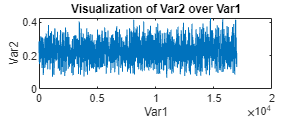

 
[rawData, feature_col] = load_rawData();

# 2. Preprocess Raw Data

Here, we take the raw data and transform it into a more digestible format for our neural network. This involves generating sequences of data to serve as input-output pairs for model training. By defining specific window sizes and strides, we can capture patterns in the data over varying time intervals. Additionally, the data is divided into training, validation, and test subsets, ensuring a proper structure for model evaluation.

 ** 2.1 Define function to generate datasets from raw temporal data**

The function `generate_dataset` facilitates the creation of input-output sequence pairs from a specified raw dataset. Its purpose is to process raw data, extracting sequences determined by defined input and output window sizes, while the progression across the data is governed by a specified stride. Users provide five essential parameters: the raw data table (`rawData`), the column name which contains the desired feature values (`feature_col`), the length of each input sequence (`input_window_size`), the length of each output sequence (`output_window_size`), and the step size for navigating through the raw data (`stride`). Within the function, feature values are first extracted from the designated column. The combined size of both the input and output windows is then computed, which assists in determining the maximum number of sequences derivable from the data. Utilizing this combined size, the function calculates the start and end indices for every sequence in both ***X*** (input) and ***y*** (output). With the aid of matrix operations and the `arrayfun` function, sequences are efficiently produced. These sequences are subsequently transformed from cell arrays to matrices and returned.

  **2.2 Generate dataset**

#  **Coding Activity 2**

- **Instructions:** Adjust the numeric slider to your desired values for the input and output window size, and the stride. Afterwhich, Click the button Generate Dataset button to generate a dataset based on your selected values.

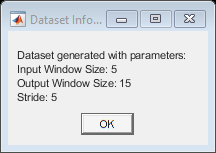

input_window_size = 5;
output_window_size = 15;
stride = 5;

 

[X, y] = generate_dataset(rawData, feature_col, input_window_size, output_window_size, stride);

msg = sprintf('Dataset generated with parameters:\nInput Window Size: %d\nOutput Window Size: %d\nStride: %d', input_window_size, output_window_size, stride);
msgbox(msg, 'Dataset Information');

  **2.3 Define function to split preprocessed dataset and reshape input sequence to be input into LSTM Model**

The function `split_and_reshape_dataset` is tailored to split the provided dataset into training, validation, and testing subsets and to reshape these subsets to be compatible with LSTM (Long Short-Term Memory) network training. Given input sequences (`X`), output sequences (`y`), a specified fraction for the test set (`test_size`), and a validation set ratio (`val_ratio`), the function generates six outputs: `X_train`, `y_train`, `X_val`, `y_val`, `X_test`, and `y_test`, representing the respective training, validation, and testing subsets for both input and output sequences. Within the function, the total number of samples is computed, and a random permutation of indices is created to shuffle the data, ensuring a randomized allocation to the data subsets. Based on the `test_size` and `val_ratio` parameters, the function defines indices to split the data into test, validation, and training segments. The data is then allocated to these subsets using the determined indices. Furthermore, a nested function, `reshapeData`, is employed to adapt each subset for LSTM training. This reshaping is executed with the `arrayfun` function, which applies a transformation over each sequence in the dataset, converting every sequence into a separate cell. This is essential because LSTM models typically expect data in this cell-array format. The `arrayfun` function iterates over each row of the data, transposes the sequence, and populates it into a new cell, ensuring that the data is structured in the desired format for LSTM processing.

  **2.4 Split and reshape dataset**

#  **Coding Activity 3**

- **Instructions:** Click the Split & Reshape Dataset button below to prepare your dataset for training, validating, and testing the upcoming LSTM model.

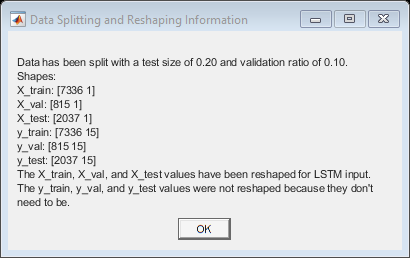

 

test_size = 0.2; 
val_ratio = 0.1;

[X_train, y_train, X_val, y_val, X_test, y_test] = split_and_reshape_dataset(X, y, test_size, val_ratio);

shapes = {size(X_train), size(X_val), size(X_test), size(y_train), size(y_val), size(y_test)};

msg = sprintf(['Data has been split with a test size of %.2f and validation ratio of %.2f.\n', ...
               'Shapes:\n', ...
               'X_train: %s\n', ...
               'X_val: %s\n', ...
               'X_test: %s\n', ...
               'y_train: %s\n', ...
               'y_val: %s\n', ...
               'y_test: %s\n', ...
               'The X_train, X_val, and X_test values have been reshaped for LSTM input.\n', ...
               'The y_train, y_val, and y_test values were not reshaped because they don''t need to be.'], ...
               test_size, val_ratio, mat2str(shapes{1}), mat2str(shapes{2}), mat2str(shapes{3}), mat2str(shapes{4}), mat2str(shapes{5}), mat2str(shapes{6}));

msgbox(msg, 'Data Splitting and Reshaping Information');

# 3. Train LSTM Model

In this segment, we define and train an LSTM neural network using our preprocessed training and validation data. The LSTM architecture is particularly suited for sequence-based data, making it an ideal choice for our dataset. We'll set up specific training parameters and monitor the model's learning progress to ensure optimal performance.

  **3.1 Define function to build, and train LSTM model**

The function `buildModel` is crafted to build and train an LSTM (Long Short-Term Memory) model using the provided training and validation data. It accepts training input sequences (`X_train`), training output sequences (`y_train`), validation input sequences (`X_val`), validation output sequences (`y_val`), the sizes of the input and output windows (`input_window_size` and `output_window_size`), a parameter to decide whether to visually represent training progress (`plotTrainingProgress`), and a verbosity control parameter (`verboseOutput`). The function initiates by defining the architecture of the LSTM model. This architecture comprises a sequence input layer, two LSTM layers interspersed with dropout layers for regularization, a fully connected layer, and a regression layer. The structure is tailored to process sequences of data and predict output sequences, typical of tasks like time-series forecasting. Following the model architecture definition, training options are specified. The model uses the Adam optimization algorithm and trains for a maximum of 50 epochs with mini-batches of 32 samples. The data is not shuffled during training, which is typical for time-series data to maintain sequence order. The training process also leverages the provided validation data to monitor the model's performance on unseen data. If specified by the user, the function can display the training progress visually. It also offers verbose output and stops training early if the validation performance doesn't improve for a specified number of epochs to prevent overfitting. Finally, the function employs the `trainNetwork` function to train the LSTM model using the defined architecture and training options. The trained network (`net`) and the associated training information (`info`) are returned as outputs. In essence, the `buildModel` function streamlines the process of constructing and training an LSTM model, making it straightforward to train powerful sequence models on time-series data.

  **3.2 Train LSTM model**

#  **Coding Activity 4**

- **Instructions: **Click the Train Model button below to initiate LSTM model training. Allow some time for the code to process. A training window will subsequently appear, indicating the model is in training. Once training completes, close the training window. Wait for the window figure to appear before moving on to the next sections of the tutorial.

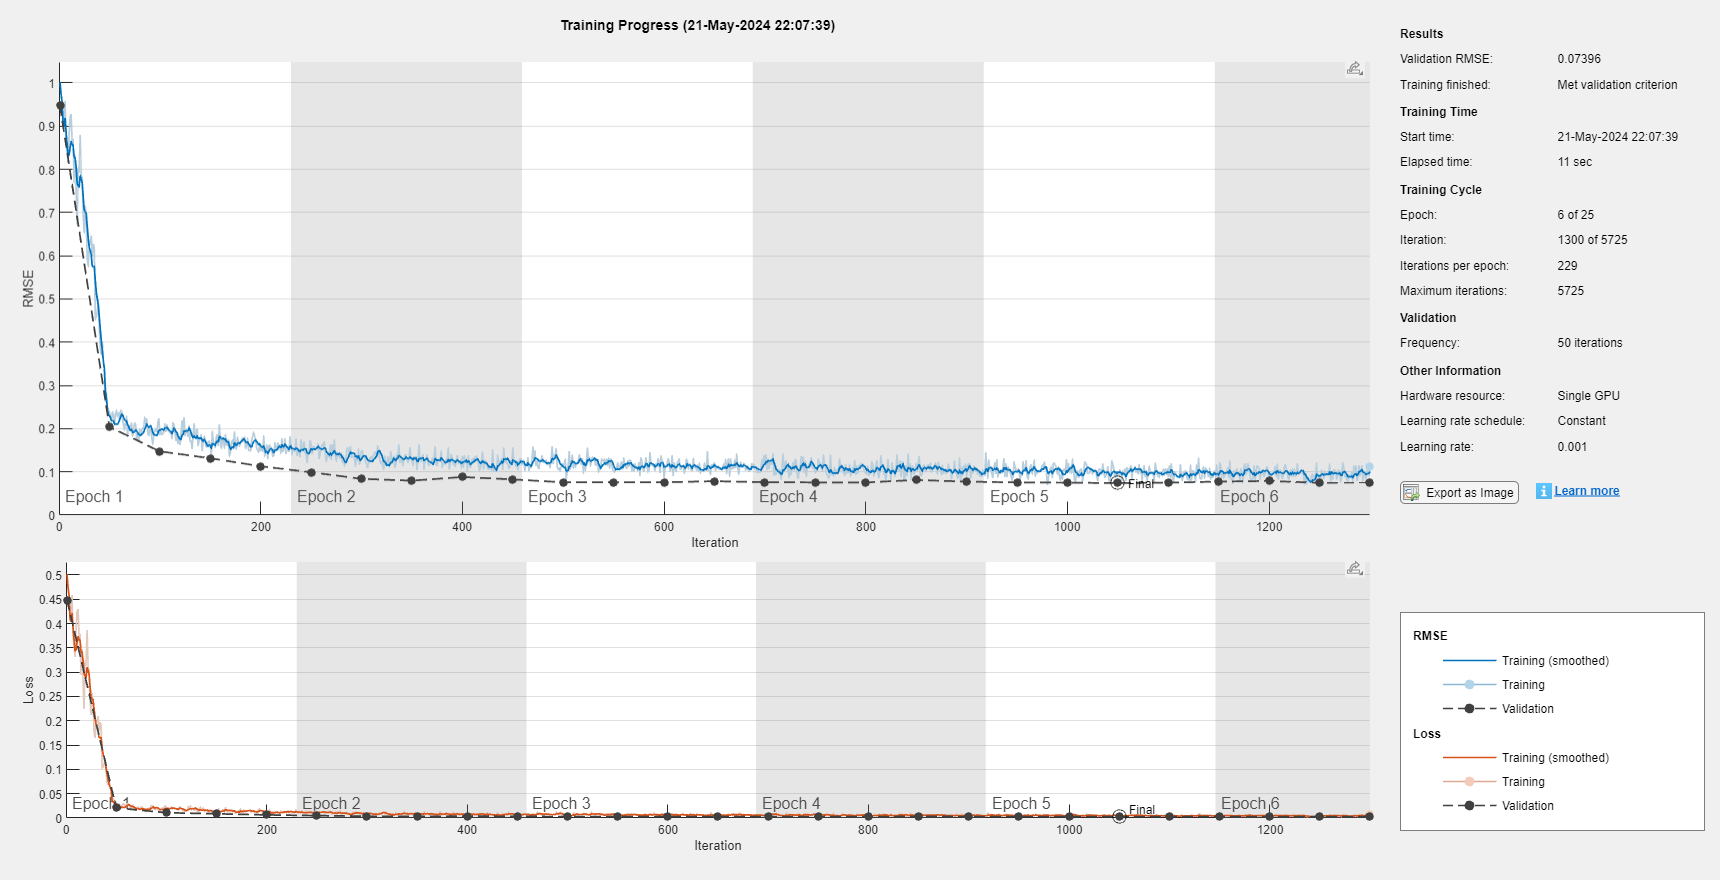

 

plotTrainingProgress = 'training-progress';  % or 'none'
verboseOutput = false;  % or true

[net, info] = buildModel(X_train, y_train, X_val, y_val, input_window_size, output_window_size, plotTrainingProgress, verboseOutput);

# 4. Test and Evaluate LSTM Model

Now that our model is trained, it's time to put it to the test. We'll utilize the reserved test data to generate predictions and then assess the model's performance against actual outcomes. Various metrics, such as MAE and RMSE, will provide insights into the accuracy and reliability of the model's predictions. Additionally, visual comparisons will offer a more tangible perspective on how the model fares.

  **4.1 Test the model by making predictions**

This line of code uses the built-in matlab `predict` function to generate predictions from the trained LSTM model, `net`, based on the input data `X_test`. The resulting predictions are stored in the variable `predictions.`

#  **Coding Activity 5**

- **Instructions: **Click the Test Model button below to produce predictions using the trained LSTM model training. Allow some time for the code to process. 

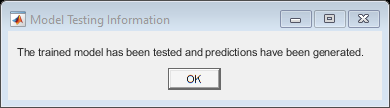

 
predictions = predict(net, X_test);

msg = 'The trained model has been tested and predictions have been generated.';
msgbox(msg, 'Model Testing Information');

  **4.2 Define function to evaluate model predictions**

The function `evaluateModel` is designed to assess the performance of a predictive model by computing various statistical metrics. Given the true test values (`y_test`) and the model's predicted values (`predictions`), this function calculates the Mean Absolute Error (MAE), Root Mean Square Error (RMSE), R-squared value, and Explained Variance. The MAE measures the average magnitude of the errors between the predicted and actual values, while the RMSE provides the square root of the average squared differences between predictions and actual observations. The R-squared value gauges the proportion of the variance in the dependent variable that is predictable from the independent variable(s), and the Explained Variance score measures the proportion of total variance captured by the model. After computing these metrics, the function organizes them into a table, labeled with their respective names. This table, `metrics`, is returned as the output, offering a consolidated view of the model's performance across different evaluation criteria.

 ** 4.3 Evaluate model predictions**

#  **Coding Activity 6**

- **Instructions: **Click the Evaluate Model button below to evaluate the LSTM model predictions. A table will be produced, displaying various metric per the `evaluateModel `function. 

 
metrics = evaluateModel(y_test, predictions);
disp(metrics);

      MAE         RMSE      R-squared    Explained Variance
    ________    ________    _________    __________________

    0.014358    0.019924     0.91468           0.9153      



  **4.4 Define function to visualize local comparison of model predictions**

The `plot_localComparison` function is tailored to visually compare the predictions made by a model against the true test values. Specifically, this function generates visualizations to offer insights into how closely the model's predictions align with the actual values across defined input and output windows. Given the testing input sequences (`X_test`), true test values (`y_test`), model's predictions (`predictions`), sizes of the input (`input_window_size`) and output (`output_window_size`) windows, and the stride (`stride`), this function crafts plots for a detailed comparison. The combined length of the input and output windows is first determined. The visualization process begins by initializing a figure and defining colors to distinguish specific samples. In a unique touch, the function spotlights two random test samples, illustrating a side-by-side depiction of the input sequence, the true future values, and the predicted future values for these samples. This close-up view serves as a detailed examination of the model's performance on individual instances. The function culminates in a comprehensive visualization that contrasts the predicted test values with the true test values for the entire dataset. Notably, the two samples chosen for the detailed view are highlighted in this overall comparison, providing context and allowing for easy cross-reference. The final outcome is an informative visualization that not only provides a macro-level overview of the model's performance across the test set but also zooms into specific instances, offering a granular perspective. 

 ** 4.5 visualize local comparison of model predictions**

#  **Coding Activity 7**

- **Instructions: **Click the Visualize Model Predictions button below to produce plots based on the model predictions, per the `plot_localComparison `function. Allow the code some time to run.

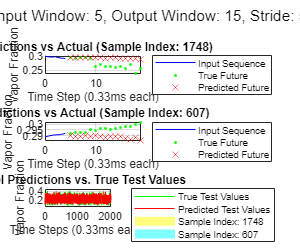

 
plot_localComparison(X_test, y_test, predictions, input_window_size, output_window_size, stride)

# 5. Conduct Parametric Study

Now that our model is trained, it's time to put it to the test. We'll utilize the reserved test data to generate predictions and then assess the model's performance against actual outcomes. Various metrics, such as MAE and RMSE, will provide insights into the accuracy and reliability of the model's predictions. Additionally, visual comparisons will offer a more tangible perspective on how the model fares.

 ** 5.1 Define a function to perform a parametric study on the LSTM model**

The function `parametric_study` conducts a comprehensive analysis of a model's performance by systematically varying key parameters: input window sizes, output window sizes, and strides. The goal is to understand how these parameters influence the model's predictive accuracy. Given a raw dataset (`rawData`), vectors of potential values for input window sizes (`para_input_window_sizes`), output window sizes (`para_output_window_sizes`), and strides (`para_strides`), the function assesses the model's performance across each combination of these parameters. Initially, the function identifies the column name of the feature under investigation and prepares an empty structure to store results. It then iterates over each combination of the provided strides, input window sizes, and output window sizes. For every combination, the dataset is first generated using the `generate_dataset` function. This dataset is then divided into training, validation, and testing subsets. A model is subsequently built and trained for the specific parameter combination using the `buildModel` function. Predictions are made on the test data using this trained model. During the iteration, the function provides real-time feedback by displaying the current combination of parameters being processed. Each set of results, comprising the true test values and the model's predictions, is stored in the `results` structure. The structure's keys are constructed using the specific combination of parameters, allowing for easy referencing and analysis later.

 ** 5.2 Perform Parametric Study**

#  **Coding Activity 8**

- **Instructions:** From the drop down boxes below, select your desired values for the input and output window sizes, and the strides for the parametric study. Afterwhich, Click the button Perform Parametric Study on Model button to initiate the parametric study. ***Note:**** Larger combinations will take longer to compute.*

para_input_window_sizes = [25, 50, 75, 100, 125, 150, 175, 200];
para_output_window_sizes = [25, 50, 75, 100, 125, 150, 175, 200];
para_strides = [1, 5];

 

% Initialize the waitbar
total_combinations = length(para_input_window_sizes) * length(para_output_window_sizes) * length(para_strides);
w = waitbar(0, 'Starting parametric study...');

% Perform parametric study
results = parametric_study(rawData, para_input_window_sizes, para_output_window_sizes, para_strides, w, total_combinations);

% Close the waitbar
close(w);

% Extract the keys (combinations) from the results struct
combinations_cell = fieldnames(results);

% Convert the keys to a more descriptive format
combinations_cell_descriptive = cellfun(@(x) strrep(strrep(strrep(x, 'S', 'Stride= '), 'I', ', Input Window Size= '), 'O', ', Output Window Size= '), combinations_cell, 'UniformOutput', false);

% Convert cell array to single string for the message box using the descriptive format
combinations_str = strjoin(combinations_cell_descriptive, '\n');
msg = sprintf('The parametric study has been completed for the following combinations:\n%s', combinations_str);
msgbox(msg, 'Parametric Study Completion');

 ** 5.3 Define function to evaluate parametric study**

The function `evaluateParametricStudy` is designed to assess and visualize the performance outcomes of a parametric study on a predictive model. Specifically, it calculates evaluation metrics for various combinations of input and output window sizes and strides that were previously used to train the model. This function provides a holistic view of the model's performance across these parameter combinations, aiding in identifying the optimal settings. Upon receiving vectors of input window sizes (`para_input_window_sizes`), output window sizes (`para_output_window_sizes`), strides (`para_strides`), and the `results` structure (which contains true values and model predictions for each parameter combination), the function initiates the evaluation process. It sets up matrices to store aggregated metrics and Mean Absolute Error (MAE) values for subsequent heatmap visualizations. The function then systematically loops through every combination of the provided strides, input window sizes, and output window sizes. For each combination, it fetches the corresponding true values and predictions from the `results` structure. The model's performance for the current parameter set is evaluated using the `evaluateModel` function, which yields metrics like MAE, RMSE, R-squared, and Explained Variance. These metrics, along with the parameters, are stored in a combined data matrix. Once all combinations are evaluated, the function transforms the aggregated metrics into a table and displays it, offering a tabulated view of the model's performance across the parameter space. Furthermore, to provide a visual perspective, the function plots heatmaps of the MAE values for each stride, with axes representing the input and output window sizes. These heatmaps vividly illustrate the model's accuracy patterns across parameter combinations, making it easier to discern trends or optimal settings.

 ** 5.4 Evaluate Parametric Study**

#  **Coding Activity 9**

**Instructions: **Click the Evaluate Parametric Study button below to display the performance metrics and plots, per the `evaluateParametricStudy` function. Allow the code some time to run.

 
evaluateParametricStudy(para_input_window_sizes, para_output_window_sizes, para_strides, results);

# **-End of Tutorial-**

## **Version 11**

**Revised on May 21, 2024 @ 9:17pm**

**Created by Najee I. Stubbs; {nistubbs@uark.edu}**

**University of Arkansas, College of Engineering, Mechanical Engineering Department**

# **Appendix: Supporting Functions**

#### A. Function to load and visualize raw data

function [rawData, feature_col] = load_rawData()
    % load_rawData Loads and visualizes raw data from a selected file.
    %
    % Outputs:
    %   rawData     - The table of raw data read from the file.
    %   feature_col - The name of the feature column (2nd column).
    %
    % This function allows the user to select a .txt file using the GUI, reads
    % the file, displays the first few rows and a summary, and then visualizes
    % the data using a plot.

    % Prompt user to select a file
    [filename, filepath] = uigetfile('*.txt', 'Select a data file');
    
    % Read the table from the file
    rawData = readtable(fullfile(filepath, filename), 'Delimiter', '\t', 'VariableNamingRule', 'preserve');
    
    % Display the first few rows and a summary of the table
    head(rawData);
    summary(rawData);
    
    % Extract the name of the feature column (2nd column)
    feature_col = rawData.Properties.VariableNames{2};
    
    % Create a plot visualizing the data from the first two columns
    figure('Position', [10, 10, 1000, 400]);
    plot(rawData{:,1}, rawData{:,2});
    xlabel(rawData.Properties.VariableNames{1});
    ylabel(feature_col);
    title(['Visualization of ', feature_col, ' over ', rawData.Properties.VariableNames{1}]);
end

#### B.1. Function to preprocess raw data

function [X, y] = generate_dataset(rawData, feature_col, input_window_size, output_window_size, stride)
    % generate_dataset Generates input-output sequence pairs from raw data.
    %
    % This function takes in raw data and extracts sequences of a specified
    % length for inputs (X) and outputs (y) based on given window sizes and stride.
    %
    % Inputs:
    %   rawData          - The table containing raw data.
    %   feature_col      - The column name in rawData that contains the desired feature values.
    %   input_window_size - The number of consecutive samples in each input sequence.
    %   output_window_size - The number of consecutive samples in each output sequence.
    %   stride            - The step size for moving the window across the rawData.
    %
    % Outputs:
    %   X                 - Matrix containing input sequences. Each row is a sequence.
    %   y                 - Matrix containing output sequences. Each row is a sequence.
    
    % Extract the feature values from the specified column in rawData.
    feature_values = rawData.(feature_col);
    
    % Calculate the total window size (input + output).
    total_window_size = input_window_size + output_window_size;
    
    % Calculate the maximum number of sequences that can be generated.
    max_num_sequences = floor((length(feature_values) - total_window_size + 1) / stride);

    % Compute the start and end indices for each sequence in X and y.
    idx_start = (0:(max_num_sequences-1))' * stride + 1;
    idx_x_end = idx_start + input_window_size - 1;
    idx_y_start = idx_x_end + 1;
    idx_y_end = idx_start + total_window_size - 1;

    % Generate the sequences for X and y using matrix operations.
    % Convert the cell arrays to matrices using cell2mat.
    X = cell2mat(arrayfun(@(s, e) feature_values(s:e)', idx_start, idx_x_end, 'UniformOutput', false));
    y = cell2mat(arrayfun(@(s, e) feature_values(s:e)', idx_y_start, idx_y_end, 'UniformOutput', false));
end

#### B.2. Function to split preprocessed dataset and reshape input sequence to be input into LSTM Model

function [X_train, y_train, X_val, y_val, X_test, y_test] = split_and_reshape_dataset(X, y, test_size, val_ratio)
    % split_and_reshape_dataset Splits and reshapes the dataset for LSTM training.
    %
    % Inputs:
    %   X          - Input sequences
    %   y          - Output sequences
    %   test_size  - Fraction of data for testing
    %   val_ratio  - Fraction of non-test data for validation
    %
    % Outputs:
    %   X_train    - Training input sequences
    %   y_train    - Training output sequences
    %   X_val      - Validation input sequences
    %   y_val      - Validation output sequences
    %   X_test     - Testing input sequences
    %   y_test     - Testing output sequences
    
    % Determine the total number of samples and generate a random permutation for data shuffling
    total_samples = length(y);
    idx = randperm(total_samples);
    
    % Split indices for test, validation, and training
    test_end = floor(total_samples * test_size);
    val_end = test_end + floor((total_samples - test_end) * val_ratio);
    
    % Assign data to sets based on the split indices
    X_test = reshapeData(X(idx(1:test_end), :));
    y_test = y(idx(1:test_end), :);
    X_val = reshapeData(X(idx(test_end+1:val_end), :));
    y_val = y(idx(test_end+1:val_end), :);
    X_train = reshapeData(X(idx(val_end+1:end), :));
    y_train = y(idx(val_end+1:end), :);
    
    function reshapedData = reshapeData(data)
        reshapedData = arrayfun(@(idx) data(idx,:)', 1:size(data,1), 'UniformOutput', false)';
    end
end

#### C. Function to build, and train LSTM model

function [net, info] = buildModel(X_train, y_train, X_val, y_val, input_window_size, output_window_size, plotTrainingProgress, verboseOutput)
    % buildModel Builds and trains an LSTM model
    %
    % Inputs:
    %   X_train            - Training input sequences
    %   y_train            - Training output sequences
    %   X_val              - Validation input sequences
    %   y_val              - Validation output sequences
    %   input_window_size  - Size of the input window
    %   output_window_size - Size of the output window
    %   plotTrainingProgress - 'training-progress' to plot training progress, or 'none' to skip
    %   verboseOutput      - true for verbose output, false otherwise
    %
    % Outputs:
    %   net                - Trained network
    %   info               - Training information
    %
    % This function builds an LSTM model, sets the training options, and then
    % trains the model on the provided training and validation data.

    % Define the layers
    layers = [ ...
        sequenceInputLayer(input_window_size, 'Normalization', 'none', 'Name', 'input')
        lstmLayer(50, 'OutputMode', 'sequence', 'Name', 'lstm1')
        dropoutLayer(0.2, 'Name', 'drop1')
        lstmLayer(50, 'OutputMode', 'last', 'Name', 'lstm2')
        dropoutLayer(0.2, 'Name', 'drop2')
        fullyConnectedLayer(output_window_size, 'Name', 'fc')
        regressionLayer('Name', 'regression')];

    % Define the training options
    options = trainingOptions('adam', ...
        'MaxEpochs', 25, ...
        'MiniBatchSize', 32, ...
        'Shuffle', 'never', ...
        'ValidationData', {X_val, y_val}, ...
        'Plots', plotTrainingProgress, ...
        'Verbose', verboseOutput, ...
        'OutputNetwork','best-validation-loss',...
        'ValidationPatience', 5, ...
        'DispatchInBackground',true,...
        'ExecutionEnvironment', 'auto');

    % Train the model
    [net, info] = trainNetwork(X_train, y_train, layers, options);
end

#### D.1. Function to evaluate model predictions

function metrics = evaluateModel(y_test, predictions)
    % evaluateModel Evaluates the model's performance using various metrics
    %
    % Inputs:
    %   y_test      - True values for testing
    %   predictions - Predicted values by the model
    %
    % Outputs:
    %   metrics     - Table containing MAE, RMSE, R-squared, and Explained Variance metrics
    %
    % This function computes various performance metrics including Mean Absolute Error (MAE),
    % Root Mean Square Error (RMSE), R-squared, and Explained Variance for the model's predictions.

    % Compute MAE
    mae = mean(abs(y_test - predictions), 'all');

    % Compute RMSE
    rmse = sqrt(mean((y_test - predictions).^2, 'all'));

    % Compute R-squared
    SST = sum((y_test - mean(y_test, 'all')).^2, 'all');
    SSR = sum((predictions - y_test).^2, 'all');
    r2_val = 1 - (SSR/SST);

    % Compute Explained Variance
    explained_var = 1 - var(y_test - predictions, 0, 'all') / var(y_test, 0, 'all');

    % Create table of metrics
    metrics = table(mae, rmse, r2_val, explained_var, 'VariableNames', {'MAE', 'RMSE', 'R-squared', 'Explained Variance'});
end

#### D.2. Function to visualize local comparison of model predictions

function plot_localComparison(X_test, y_test, predictions, input_window_size, output_window_size, stride)
    % plot_localComparison Visualizes the comparison of model predictions against true values.
    %
    % Inputs:
    %   X_test            - Testing input sequences
    %   y_test            - True values for testing
    %   predictions       - Predicted values by the model
    %   input_window_size  - Size of the input window
    %   output_window_size - Size of the output window
    %   stride            - Stride for sliding window
    %
    % This function visualizes the comparison of the model's predictions against the true values for a random
    % set of test samples. The visualization provides insights into how closely the model's predictions match 
    % the true values over the input and output windows.

    % Calculate the total window size
    total_window_size = input_window_size + output_window_size;
    
    % Initialize the figure with specified position
    figure('Position', [60, 15, 1800, 1500]);

    % Define colors for highlighting specific samples in the plots
    colors = {'yellow', 'cyan'};
    
    % Array to store indices of samples chosen for detailed visualization
    highlighted_indices = zeros(1, 2);  

    % Get the number of samples in the test set
    num_samples = size(X_test, 1);

    % Visualize detailed comparison for two random test samples
    for i = 1:2
        subplot(3, 1, i);
        
        % Select a random sample index
        rand_idx = randi(num_samples);
        highlighted_indices(i) = rand_idx;

        % Plot the input sequence, true future, and predicted future for the selected sample
        plot(0:input_window_size-1, X_test{rand_idx}, 'b-', 'DisplayName', 'Input Sequence');
        hold on;
        plot(input_window_size:total_window_size-1, y_test(rand_idx, :), 'g.', 'DisplayName', 'True Future');
        plot(input_window_size:total_window_size-1, predictions(rand_idx, :), 'rx', 'DisplayName', 'Predicted Future');

        % Configure the subplot
        legend('Location', 'eastoutside');
        title(['Predictions vs Actual (Sample Index: ', num2str(rand_idx), ')']);
        xlabel('Time Step (0.33ms each)');
        ylabel('Vapor Fraction');
        xlim([0, total_window_size-1]);
        grid on;
    end

    % Visualize the overall comparison for all test samples
    subplot(3, 1, 3);
    y_test_last_values = y_test(:, end);
    y_pred_last_values = predictions(:, end);

    plot(y_test_last_values, 'g-', 'DisplayName', 'True Test Values');
    hold on;
    plot(y_pred_last_values, 'r-', 'DisplayName', 'Predicted Test Values');

    % Highlight the samples chosen for detailed visualization
    yLims = ylim;
    for k = 1:length(highlighted_indices)
        idx = highlighted_indices(k);
        patchColor = colors{k};
        patch([idx-0.5, idx+0.5, idx+0.5, idx-0.5], [yLims(1), yLims(1), yLims(2), yLims(2)], patchColor, 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', ['Sample Index: ' num2str(idx)]);
    end

    % Configure the plot
    ylim(yLims);
    xlim([0, size(y_test, 1)]);
    legend('Location', 'eastoutside');
    title('Model Predictions vs. True Test Values');
    xlabel('Time Steps (0.33ms each)');
    ylabel('Vapor Fraction');
    grid on;

    % Add a title for the entire figure
    sgtitle(['Input Window: ' num2str(input_window_size) ', Output Window: ' num2str(output_window_size) ', Stride: ' num2str(stride)]);
end

#### E.1. Function to perform parametric study of parameters: input_window_size, output_window_size, stride

function [results] = parametric_study(rawData, para_input_window_sizes, para_output_window_sizes, para_strides, w, total_combinations)
    %parametric_study Conducts a study of model performance over various parameters.
    %
    % This function iterates over different combinations of input and output window sizes, 
    % and strides to train models and make predictions. The results are stored in a structure
    % for further analysis.
    %
    % Inputs:
    %   rawData                 - The table of raw data.
    %   para_input_window_sizes - Vector of input window sizes for the study.
    %   para_output_window_sizes- Vector of output window sizes for the study.
    %   para_strides            - Vector of strides for the study.
    %
    % Outputs:
    %   results                 - Struct containing true values and predictions for each parameter combination.
    
    % Extract the column name for the feature of interest
    feature_col = rawData.Properties.VariableNames{2};
    
    % Initialize results structure
    results = struct();

    % Counter for updating waitbar
    count = 0;

    % Loop through all combinations of strides, input and output window sizes
    for s = para_strides
        for i = para_input_window_sizes
            for j = para_output_window_sizes
                % Update count
                count = count + 1;
                
                % Update the waitbar
                waitbar(count/total_combinations, w, sprintf('Processing: stride=%d, input size=%d, output size=%d', s, i, j));
                
                % Generate dataset for current combination
                [X, y] = generate_dataset(rawData, feature_col, i, j, s);
                
                % Split the dataset into training, validation, and testing subsets
                [X_train, y_train, X_val, y_val, X_test, y_test] = split_and_reshape_dataset(X, y, 0.2, 0.1);
                
                % Build and train the model for current combination
                [net, ~] = buildModel(X_train, y_train, X_val, y_val, i, j, 'none', false);
                
                % Make predictions using the trained model
                predictions = predict(net, X_test);
                
                % Construct the key to store the specific result in the 'results' struct
                resultKey = ['S', num2str(s), '_I', num2str(i), '_O', num2str(j)];
                
                % Store the true values and predictions in the results struct
                results.(resultKey) = struct('true_values', y_test, 'predictions', predictions);
            end
        end
    end
end

#### E.2. Function to evaluate and visualize 3D matrix of parametric study results

function evaluateParametricStudy(para_input_window_sizes, para_output_window_sizes, para_strides, results)
    %evaluateParametricStudy Evaluates the results from a parametric study of model performance.
    %
    % This function computes and aggregates the evaluation metrics for various combinations 
    % of input and output window sizes, and strides. The results are then displayed as 
    % a table and heatmaps.
    %
    % Inputs:
    %   para_input_window_sizes  - Vector of input window sizes for the study.
    %   para_output_window_sizes - Vector of output window sizes for the study.
    %   para_strides             - Vector of strides for the study.
    %   results                  - Struct containing true values and predictions for each parameter combination.
    %
    % Outputs:
    %   Displays a table of metrics and heatmaps visualizing the Mean Absolute Error (MAE) for each stride.

    % Calculate the number of different parameters
    num_strides = length(para_strides);
    num_inputs = length(para_input_window_sizes);
    num_outputs = length(para_output_window_sizes);

    % Initialize matrix for aggregated metrics data
    combined_data = zeros(num_strides * num_inputs * num_outputs, 7);

    % Initialize matrix to store MAE values for heatmaps
    heatmap_values = zeros(num_inputs, num_outputs, num_strides);

    idx = 1; % Index to track row position in combined_data matrix

    % Loop through all combinations of strides, input and output window sizes
    for s = 1:num_strides
        stride_str = num2str(para_strides(s));
        
        for i = 1:num_inputs
            input_str = num2str(para_input_window_sizes(i));
            
            for j = 1:num_outputs
                output_str = num2str(para_output_window_sizes(j));
                
                % Construct the key to retrieve the specific result from the 'results' struct
                resultKey = ['S', stride_str, '_I', input_str, '_O', output_str];
                current_result = results.(resultKey);

                % Evaluate the model for current combination
                metrics = evaluateModel(current_result.true_values, current_result.predictions);

                % Store the calculated metrics and parameters in the combined_data matrix
                combined_data(idx, :) = [para_strides(s), para_input_window_sizes(i), para_output_window_sizes(j), metrics.MAE, metrics.RMSE, metrics.('R-squared'), metrics.('Explained Variance')];
                idx = idx + 1;

                % Update the heatmap values matrix
                heatmap_values(i, j, s) = metrics.MAE;
            end
        end
    end

    % Convert the combined data matrix to a table and display it
    table = array2table(combined_data, 'VariableNames', {'Stride', 'Input_Window', 'Output_Window', 'MAE', 'RMSE', 'R-squared', 'Explained Variance'});
    disp(table);

    % Plot heatmaps for each stride
    for s = 1:num_strides
        figure;
        heatmap(para_output_window_sizes, para_input_window_sizes, heatmap_values(:,:,s), 'Colormap', parula);
        title(['MAE for Stride ', num2str(para_strides(s))]);
        xlabel('Output Sequence Length');
        ylabel('Input Sequence Length');
        colorbar;
    end
end